# Ripartizione trasversale ponte a cassoncino

% ponte semplicemente appoggiato
%% Clear workspace and close any open windows
clear all
close all

## DATI 

a = 2500 ;                % interasse cassoncini [mm]
L = 25*1000 ;                  % lunghezza trave [mm]
E = 34545 ;               % modulo elastico cls 45/55 [N/mm2]
G = 14199 ;               % modulo elastico tangenziale cls 45/55 [N/mm2]
A = 1262233 ;             % Area cassoncino [mm^2]
J = 1592582*10^4 ;       %  momento d'inerzia cassoncino [mm^4]
c = ( 2*(139/14) + 2*(63/34) + 85/19 + 120/25 ) ;  % sum bj/sj
Jt = 4*A^2/c            % rigidezza torsionale

Jt =  194079391559.13


alpha = pi*a/(2*L)*sqrt(E*J/(G*Jt)) 

alpha =           0.07


% CARICHI
P1 = 2*600/25*0.75 ; % KN
xp1 = 12.5;
P2 = 2*600/25*0.75 ;
xp2 = 12.5;
P3 = 2*400/25*0.75;
xp3 = 12.5;
P4 = 2*400/25*0.75 ;
xp4 = 12.5;

l = L/1000 ;
x=0:l/(500):l;
%w = logspace(-1, 1, 1000);

## Equazioni

syms  va vb vc real

for j =1:64
    if mod (j, 2) == 0 % pari
        
        Q = 0*[P1  P2  P3  P4];    
        
    else
        
        Q = (2*l/(pi*j) )*[P1*sin(j*pi*xp1/l)  P2*sin(j*pi*xp2/l)  P3*sin(j*pi*xp3/l)  P4*sin(j*pi*xp4/l)];

    end

    Eq1 = 2*va*(1 + j^2*alpha^2) - vb*(1- j^2*alpha^2) == 2/l*(Q(2) - Q(1));
    Eq2 = -va*(1 - j^2*alpha^2) + 2*vb*(1 + j^2*alpha^2) - vc*(1- j^2*alpha^2) == 2/l*(Q(3) - Q(2));
    Eq3 = -vb*(1 - j^2*alpha^2) + 2*vc*(1 + j^2*alpha^2) - 0 == 2/l*(Q(4) - Q(3));
  

    S = solve([Eq1 Eq2 Eq3],[va vb vc]); 


## Tagli sui cassoncini

% in [KN/m]
    vn_a(j) = (S.va(1));
    vn_b(j) = (S.vb(1));
    vn_c(j) = (S.vc(1));
    

## Forze sui cassoncini

     t1(j) = double(2/l*Q(1) + vn_a(j) - 0 );
     t2(j) = double(2/l*Q(2) + vn_b(j) - vn_a(j) );
     t3(j) = double(2/l*Q(3) + vn_c(j) - vn_b(j) );
     t4(j) = double(2/l*Q(4) + 0 - vn_c(j) );


## spostamenti cassoncini

% in [mm]

    wa(j) =  L^4/(j^4*pi^4*E*J)*t1(j);
    wb(j) =  L^4/(j^4*pi^4*E*J)*t2(j) ;
    wc(j) =  L^4/(j^4*pi^4*E*J)*t3(j) ;
    wd(j) =  L^4/(j^4*pi^4*E*J)*t4(j) ;


## rotazione cassoncini

% in [ 1 / mm ]

    rxa(j) =  L^2*a/(2*j^2*pi^2*G*Jt) * (vn_a(j) + 0) ;
    rxb(j) =  L^2*a/(2*j^2*pi^2*G*Jt) * (vn_b(j) + vn_a(j));
    rxc(j) =  L^2*a/(2*j^2*pi^2*G*Jt) * (vn_c(j) + vn_b(j));
    rxd(j) =  L^2*a/(2*j^2*pi^2*G*Jt) * (0 + vn_c(j));


## Andamento forze lungo l'asse del ponte

    % Carico sui cassoncini [KN/m]
       
    qa(j,:) = t1(j)*sin(j*pi*x/l);
    qb(j,:) = t2(j)*sin(j*pi*x/l);
    qc(j,:) = t3(j)*sin(j*pi*x/l);
    qd(j,:) = t4(j)*sin(j*pi*x/l);
    
    % Taglio sui cassoncini [KN]
    Ta(j,:) = t1(j)*l/(j*pi)*cos(j*pi*x/l);
    Tb(j,:) = t2(j)*l/(j*pi)*cos(j*pi*x/l);
    Tc(j,:) = t3(j)*l/(j*pi)*cos(j*pi*x/l);
    Td(j,:) = t4(j)*l/(j*pi)*cos(j*pi*x/l); 
    
    % Momento sui cassoncini [KNm]
    Ma(j,:) = t1(j)*l^2/(j^2*pi^2)*sin(j*pi*x/l);
    Mb(j,:) = t2(j)*l^2/(j^2*pi^2)*sin(j*pi*x/l);
    Mc(j,:) = t3(j)*l^2/(j^2*pi^2)*sin(j*pi*x/l);
    Md(j,:) = t4(j)*l^2/(j^2*pi^2)*sin(j*pi*x/l);      
    
    
    
    % spostamenti sui cassoncini [mm]
    Wa(j,:) = wa(j)*sin(j*pi*x/l);
    Wb(j,:) = wb(j)*sin(j*pi*x/l);
    Wc(j,:) = wc(j)*sin(j*pi*x/l);
    Wd(j,:) = wd(j)*sin(j*pi*x/l);
    
    % rotazioni sui cassoncini []
    Rxa(j,:) = rxa(j)*sin(j*pi*x/l);
    Rxb(j,:) = rxb(j)*sin(j*pi*x/l);
    Rxc(j,:) = rxc(j)*sin(j*pi*x/l);
    Rxd(j,:) = rxd(j)*sin(j*pi*x/l); 
    
    % Momento torcente sui cassoncini KN*m
    
    Mta(j,:) =  a/2 * (vn_a(j) + 0)*sin(j*pi*x/l) ;
    Mtb(j,:) =  a/2 * (vn_b(j) + vn_a(j))*sin(j*pi*x/l);
    Mtc(j,:) =  a/2 * (vn_c(j) + vn_b(j))*sin(j*pi*x/l);
    Mtd(j,:) =  a/2 * (0 + vn_c(j))*sin(j*pi*x/l);
   
end

## SOMMA ITERAZIONI

q = [sum(qa); sum(qb); sum(qc); sum(qd)]; % carico per unità di lunghezza
Rx = [sum(Rxa); sum(Rxb); sum(Rxc); sum(Rxd)]; % rotazione
W = [sum(Wa); sum(Wb); sum(Wc); sum(Wd)]; % spostamento
T = [sum(Ta); sum(Tb); sum(Tc); sum(Td)]; % taglio
M = [sum(Ma); sum(Mb); sum(Mc); sum(Md)]; % momento flettente
Mt = [sum(Mta); sum(Mtb); sum(Mtc); sum(Mtd)]; % momento torcente

## PLOT

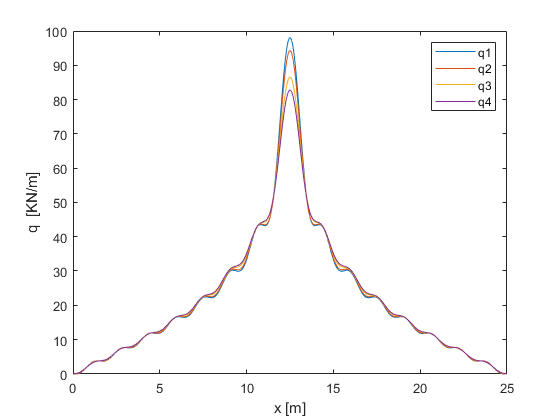

% PLOT forze su cassoncini

figure()
plot(x,q)

% title(['\fontname{Courier}\fontsize{15}Deformazione w_(_z_)'],'color','K');
ylabel('q  [KN/m]');
xlabel('x [m]');
legend('q1','q2','q3','q4')

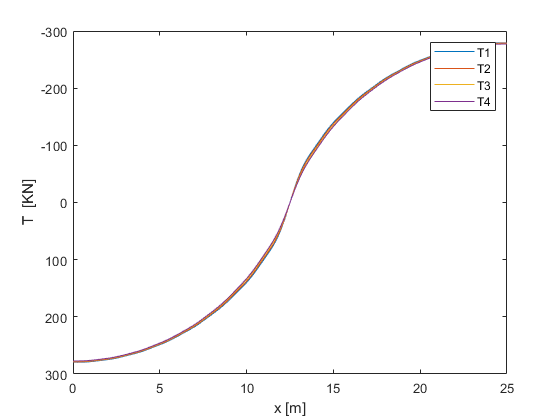

%axis square

% PLOT TAGLIO

figure()
plot(x,T)

% title(['\fontname{Courier}\fontsize{15}Deformazione w_(_z_)'],'color','K');
ylabel('T  [KN]');
xlabel('x [m]');
legend('T1','T2','T3','T4')
axis ij

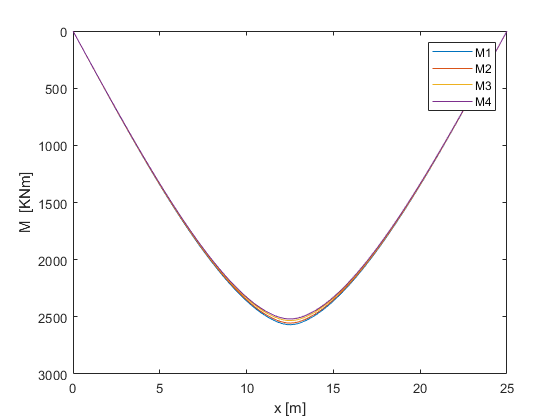

% PLOT MOMENTO FLETTENTE

figure()
plot(x,M)

% title(['\fontname{Courier}\fontsize{15}Deformazione w_(_z_)'],'color','K');
ylabel('M  [KNm]');
xlabel('x [m]');
legend('M1','M2','M3','M4')
axis ij

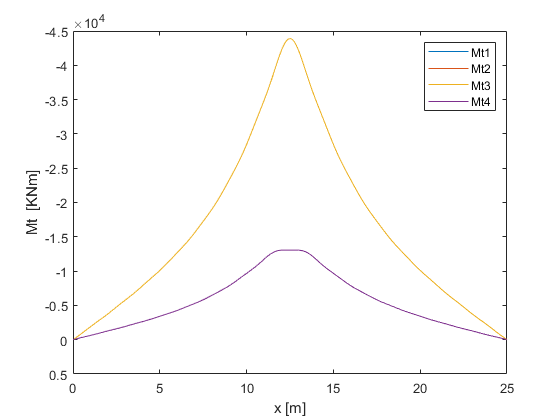

% PLOT MOMENTO TORCENTE

figure()
plot(x,Mt)

% title(['\fontname{Courier}\fontsize{15}Deformazione w_(_z_)'],'color','K');
ylabel('Mt  [KNm]');
xlabel('x [m]');
legend('Mt1','Mt2','Mt3','Mt4')
axis ij

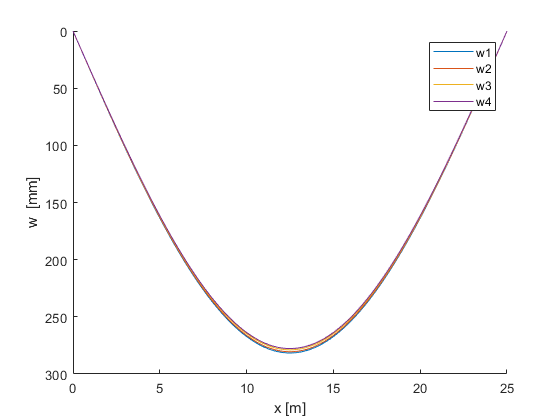

% PLOT SPOSTAMENTI

figure()
hold on
plot(x,W)

% title(['\fontname{Courier}\fontsize{15}Deformazione w_(_z_)'],'color','K');
ylabel('w  [mm]');
xlabel('x [m]');
legend('w1','w2','w3','w4')
axis ij
axis auto

%Ripartizione
M1max = max(M(1,:))

M1max =        2568.73


M2max = max(M(2,:))

M2max =        2554.52


M3max = max(M(3,:))

M3max =        2532.62


M4max = max(M(4,:))

M4max =        2518.41
